# Bluetooth BR/EDR Waveform Generation and Transmission using SDR

This example shows how to generate and transmit Bluetooth BR/EDR waveforms using the Communications Toolbox™ Library for the Bluetooth Protocol. You can either transmit the Bluetooth BR/EDR waveforms by using the ADALM-PLUTO radio or write to a baseband file (*.bb). 

To receive the transmitted Bluetooth BR/EDR waveform, refer to the Bluetooth BR/EDR Receiver example and implement any one of these setups: 

- Two SDR platforms connected to the same host computer which runs two MATLAB sessions.

- Two SDR platforms connected to two host computers which runs two separate MATLAB sessions.

 To configure your host computer to work with the Support Package for ADALM-PLUTO Radio, refer [docid:plutoradio_ug#bvn89q2-14](docid:plutoradio_ug#bvn89q2-14).

## Required Hardware

To transmit signals in real time, you need ADALM-PLUTO radio and the corresponding support package:

- [Communications Toolbox Support Package for ADALM-PLUTO Radio](https://www.mathworks.com/hardware-support/adalm-pluto-radio.html)

For a full list of Communications Toolbox supported SDR platforms, refer to Supported Hardware section of the [Software Defined Radio (SDR) discovery page](https://www.mathworks.com/discovery/sdr.html).

## Bluetooth BR/EDR Radio Specifications

Bluetooth [ 1 ] is a short-range Wireless Personal Area Network (WPAN) technology, operating in the globally unlicensed industrial, scientific, and medical (ISM) band in the frequency range 2.4 GHz to 2.485 GHz. In Bluetooth technology, data is divided into packets. Each packet is transmitted on one of the 79 designated Bluetooth channels. Each channel has a bandwidth of 1 MHz. As there are different types of wireless networks operating in the same unlicensed frequency band, it is possible for two different networks to interfere with each other. To mitigate the interference, Bluetooth implements the frequency-hopping spread spectrum (FHSS) scheme to switch a carrier between multiple frequency channels by using a pseudorandom sequence known to both the transmitter and receiver.

The Bluetooth standard specifies these physical layer (PHY) modes:

**Basic rate (BR)** - Mandatory mode, uses Gaussian frequency shift keying (GFSK) modulation with a data rate of 1 Mbps.

**Enhanced data rate (EDR)** - Optional mode, uses phase shift keying (PSK) modulation with these two variants:

- EDR2M: Uses pi/4-DQPSK with a data rate of 2 Mbps.

- EDR3M: Uses 8-DPSK with a data rate of 3 Mbps.

## Packet Formats

The air interface packet formats for PHY modes include these fields:

**Access Code**: Each packet starts with an access code. If a packet header follows, the access code is 72 bits long, otherwise the access code is 68 bits long. The access code consists of these fields:

- Preamble: The preamble is a fixed zero-one pattern of four symbols.

- Sync Word: The sync word is a 64-bit code word derived from 24-bit lower address part (LAP) of the Bluetooth device address.

- Trailer: The trailer is a fixed zero-one pattern of four symbols.

**Packet Header**: The header includes link control information and consists of these fields:

- LT_ADDR: 3-bit logical transport address.

- TYPE: 4-bit type code, which specifies the packet type used for transmission. It can be one of {ID, NULL, POLL, FHS, HV1, HV2, HV3, DV, EV3, EV4, EV5, 2-EV3, 2-EV5, 3-EV3, 3-EV5, DM1, DH1, DM3, DH3, DM5, DH5, AUX1, 2-DH1, 2-DH3, 2-DH5, 3-DH1, 3-DH3, 3-DH5}.

- FLOW: 1-bit flow control.

- ARQN: 1-bit acknowledgement indication.

- SEQN: 1-bit sequence number.

- HEC: 8-bit header error check.

**Payload**: Payload includes an optional payload header, a payload body, and an optional CRC.

**Guard**: For EDR packets, guard time allows the Bluetooth radio to prepare for the change in modulation from GFSK to DPSK. The guard time must be between 4.75 to 5.25 microseconds.

**Sync**: For EDR packets, the synchronization sequence contains one reference symbol and ten DPSK symbols.

**Trailer**: For EDR packets, the trailer bits must be all zero pattern of two symbols, {00,00} for pi/4-DQPSK and {000,000} for 8DPSK.

This figure shows the packet format for BR mode

This figure shows the packet format for EDR mode

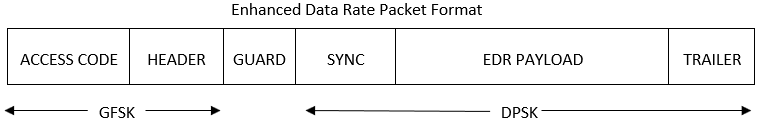

## Bluetooth BR/EDR Waveform Generation and Transmission

This example shows how to generate Bluetooth BR/EDR waveforms according to the Bluetooth specification. The spectrum and spectrogram of the generated Bluetooth BR/EDR waveforms are visualized by using the spectrum analyzer. You can transmit the generated waveforms by using the ADALM-PLUTO radio or by writing them to a baseband file (*.bb).

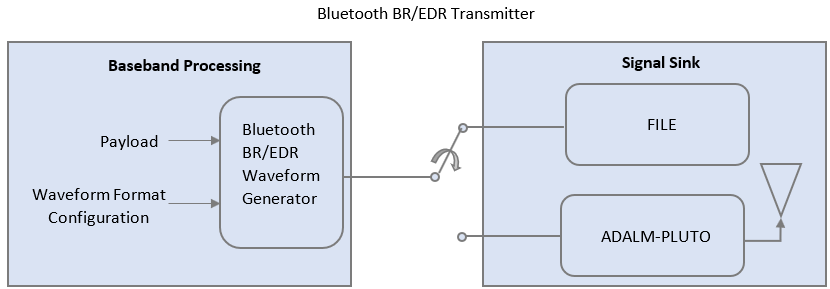

## Check for Support Package Installation

% Check if the 'Communications Toolbox Library for the Bluetooth Protocol'
% support package is installed.
commSupportPackageCheck('BLUETOOTH');

## Bluetooth BR/EDR Baseband Waveform Generation and Visualization

To configure the Bluetooth waveform generator for basic rate transmission, use the [docid:comm_ref#obj_bluetoothWaveformConfig](docid:comm_ref#obj_bluetoothWaveformConfig) object.

cfg = bluetoothWaveformConfig;
cfg.Mode = 'BR'; % Mode of transmission as one of BR, EDR2M and EDR3M
cfg.PacketType = 'HV1';     % Packet type
cfg.SamplesPerSymbol = 60; % Samples per symbol ORIGINALLY 60
cfg.ModulationIndex = 0.28;

To generate the Bluetooth BR/EDR waveforms, use the [docid:comm_ref#mw_75c12f84-8df0-40b2-8f5f-6698870beb91](docid:comm_ref#mw_75c12f84-8df0-40b2-8f5f-6698870beb91) function. The method [docid:comm_ref#getPayloadLength](docid:comm_ref#getPayloadLength) returns the required payload length for the given configuration, which is used to create a random payload for transmission.

payloadLength = getPayloadLength(cfg); % Payload length in bytes
octetLength = 8;
dataBits = randi([0 1],payloadLength*octetLength*8,1); % Generate random payload bits
txWaveform = bluetoothWaveformGenerator(dataBits,cfg); % Create Bluetooth waveform

You can configure the function [helperBluetoothPacketDuration.m](matlab:edit('helperBluetoothPacketDuration.m')) to derive Bluetooth packet duration corresponding to the generated Bluetooth symbols.

packetDuration = helperBluetoothPacketDuration(cfg.PacketType,cfg.Mode,payloadLength);

The [docid:comm_ref#bsnfizs_4](docid:comm_ref#bsnfizs_4) System object is used to perform a frequency shift for Bluetooth BR/EDR waveforms based on the channel number. In this example, the waveform is visualized by using the [docid:dsp_ref#bthj29x-1](docid:dsp_ref#bthj29x-1) System object that selects a random channel number from the range 0 to 60 as sample rate used in this example is 60 MHz.

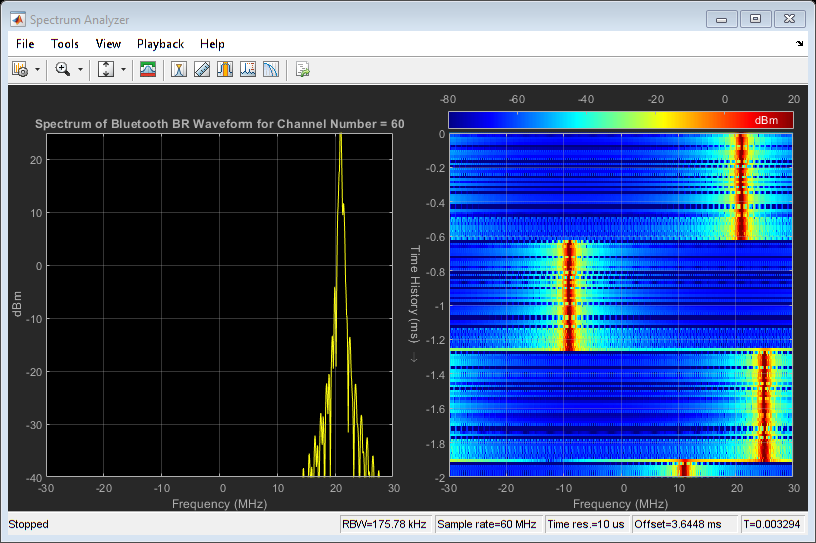

symbolRate = 1e6; % Symbol rate
sampleRate = symbolRate * cfg.SamplesPerSymbol;
numChannels = 10; % Number of channels

% Create and configure frequency offset System object
pfo = comm.PhaseFrequencyOffset('SampleRate',sampleRate);
% Create and configure spectrum analyzer System object
scope = dsp.SpectrumAnalyzer('ViewType','Spectrum and spectrogram',...
                'TimeResolutionSource','Property','TimeResolution',1e-5,...
                'SampleRate',sampleRate,'TimeSpanSource','Property',...
                'TimeSpan',2e-3,'FrequencyResolutionMethod','WindowLength',...
                'WindowLength',512,'AxesLayout','Horizontal','YLimits',[-40 25]);
% Loop over the number of channels to visaulize the frequency shift
for packetIdx = 1:numChannels
    channelNum = randsrc(1,1,0:60); % Generate random channel number
    freqIndex = channelNum - 39; % To visualize as a two sided spectrum
    pfo.FrequencyOffset = freqIndex*symbolRate; % Frequency shift
    hoppedWaveform = pfo(txWaveform(1:packetDuration*cfg.SamplesPerSymbol));
    scope.Title = ['Spectrum of Bluetooth ',cfg.Mode,...
                   ' Waveform for Channel Number = ', num2str(channelNum)];
    scope(hoppedWaveform);
end
% Release the System objects
release(scope);

release(pfo);

## Transmitter Processing

Specify the signal sink as 'File' or 'ADALM-PLUTO'.

- **File**: Uses the [docid:comm_ref#bvby020-1](docid:comm_ref#bvby020-1) System object to write a baseband file.

- **ADALM-PLUTO**: Uses the [docid:plutoradio_ref#bvn84t3-1](docid:plutoradio_ref#bvn84t3-1) System object to transmit a live signal from the SDR hardware.

% Initialize the parameters required for signal sink
txCenterFrequency = 2445000000;  % In Hz, varies between 2.402e9 to 2.480e9 with 1e6 spacing
txFrameLength     = length(txWaveform);
txNumberOfFrames  = 1e4;
bbFileName        = 'bluetoothBRCaptures.bb';

% The default signal sink is 'File'
signalSink = 'File';

if strcmp(signalSink,'File')

    sigSink = comm.BasebandFileWriter('CenterFrequency',txCenterFrequency,...
        'Filename',bbFileName,...
        'SampleRate',sampleRate);
    sigSink(txWaveform); % Writing to a baseband file 'bluetoothBRCaptures.bb'

else % For 'ADALM-PLUTO'

    % Check if the pluto Hardware Support Package (HSP) is installed
    if isempty(which('plutoradio.internal.getRootDir'))
        error(message('comm_demos:common:NoSupportPackage', ...
                      'Communications Toolbox Support Package for ADALM-PLUTO Radio',...
                      ['<a href="https://www.mathworks.com/hardware-support/' ...
                      'adalm-pluto-radio.html">ADALM-PLUTO Radio Support From Communications Toolbox</a>']));
    end
    connectedRadios = findPlutoRadio; % Discover ADALM-PLUTO radio(s) connected to your computer
    radioID = connectedRadios(1).RadioID;
    sigSink = sdrtx( 'Pluto',...
        'RadioID',           radioID,...
        'CenterFrequency',   txCenterFrequency,...
        'Gain',              0,...
        'SamplesPerFrame',   txFrameLength,...
        'BasebandSampleRate',sampleRate);
    % The transfer of baseband data to the SDR hardware is enclosed in a
    % try/catch block. This implies that if an error occurs during the
    % transmission, the hardware resources used by the SDR System
    % object are released.
    currentFrame = 1;
    try
        while currentFrame <= txNumberOfFrames
            % Data transmission
            sigSink(txWaveform);
            % Update the counter
            currentFrame = currentFrame + 1;
        end
    catch ME
        release(sigSink);
        rethrow(ME);
    end
end

% Release the signal sink
release(sigSink);

In this example, you can generate and transmit Bluetooth BR/EDR waveforms by using ADLAM-PLUTO or by writing the waveforms to a baseband file. The spectrum and spectogram of the generated Bluetooth BR/EDR waveforms is visualized by using a spectrum analyzer.

## Further Exploration

You can use this example to transmit EDR packets by changing the mode of transmission. To decode the Bluetooth BR/EDR waveform generated in this example, refer to the Bluetooth BR/EDR Receiver example.

## Troubleshooting

General tips for troubleshooting SDR hardware and the Communications Toolbox Support Package for ADALM-PLUTO Radio can be found in [docid:plutoradio_ug#bvn89q2-68](docid:plutoradio_ug#bvn89q2-68).

## Appendix

The example uses this helper function:

- [helperBluetoothPacketDuration.m](matlab:edit('helperBluetoothPacketDuration.m')): Returns Bluetooth packet duration

## Selected Bibliography

- Bluetooth Special Interest Group (SIG). "Core System Package [BR/EDR Controller Volume]". *Bluetooth Core Specification*. Version 5.1, Volume 2. [www.bluetooth.com](https://www.bluetooth.com/)

*Copyright 2019 The MathWorks, Inc.*